%% Remove_Stripe_Noise_ADOM.m
% Removes vertical stripe noise using the ADOM method.

clc; clear; close all;

% Load Striped Image
striped_img_path = "C:\Users\Mahallakshmi\OneDrive\Documents\S3_projects\Mfc_S3\Striped_Image.jpg";
img = imread(striped_img_path);

if size(img,3) > 1
    img = rgb2gray(img);
end
O_striped = im2double(img);


% Set Parameters
lambda1 = 0.05;
lambda2 = 0.1;
rho1 = 1;
rho2 = 1;
rho3 = 1;
p = 10;
tol = 1e-4;
max_iter = 200;


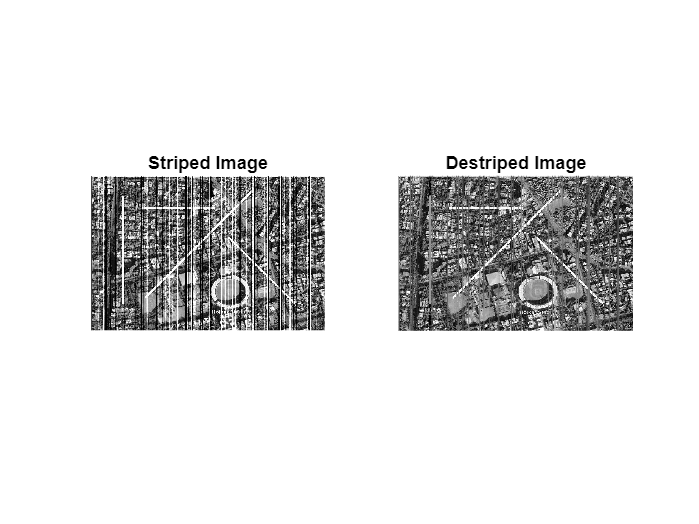

% Call ADOM Function
destriped = ADOM(O_striped, lambda1, lambda2, rho1, rho2, rho3, p, tol, max_iter);

% Display and Save Results
figure;
subplot(1,2,1); imshow(O_striped); title('Striped Image');
subplot(1,2,2); imshow(destriped); title('Destriped Image');


output_path = "C:\Users\Mahallakshmi\OneDrive\Documents\S3_projects\Mfc_S3\Destriped_Image.jpg";
imwrite(destriped, output_path);

fprintf('Destriped image saved at:\n%s\n', output_path);

Destriped image saved at:
C:\Users\Mahallakshmi\OneDrive\Documents\S3_projects\Mfc_S3\Destriped_Image.jpg


%% ADOM Function Definition

function destriped = ADOM(O, lambda1, lambda2, rho1, rho2, rho3, p, tol, max_iter)
    % ADOM: ADMM-Based Optimization Model for Stripe Noise Removal
    % Input: O - observed image (2D matrix)
    % Output: destriped - destriped image (O - S)

    if nargin < 9, max_iter = 200; end
    if nargin < 8, tol = 1e-4; end
    if nargin < 7, p = 10; end
    if nargin < 6, rho3 = 1; end
    if nargin < 5, rho2 = 1; end
    if nargin < 4, rho1 = 1; end
    if nargin < 3, lambda2 = 0.1; end
    if nargin < 2, lambda1 = 0.1; end

    [h, w] = size(O);
    delta = 0.1;
    

    % Initialization
    S = zeros(h, w);
    S_prev = S;
    tau1 = zeros(h, w);
    tau2 = zeros(h, w);
    tau3 = zeros(h, w);
    alpha = 1;
    alpha_prev = alpha;
    wn = 1;
    wg = ones(1, w);
    k = 0;

    % Frequency domain setup for FFT solver
    [Fx, Fy] = meshgrid(0:w-1, 0:h-1);
    F_x = 1 - exp(-1i * 2 * pi * Fx / w);
    F_y = 1 - exp(-1i * 2 * pi * Fy / h);
    F_x_conj = conj(F_x);
    F_y_conj = conj(F_y);
    Q = rho1 * (F_y_conj .* F_y) + rho2 * (F_x_conj .* F_x) + rho3;
    Q(Q==0) = eps;

    while k < max_iter
        k = k + 1;


        % 1. Weight Control
        res_curr = O - S;
        res_prev = O - S_prev;
        norm_res_prev = norm(res_prev, 'fro');
        if norm_res_prev == 0
            gamma = 0;
        else
            gamma = norm(res_curr - res_prev, 'fro') / norm_res_prev;
        end
        if alpha - gamma ~= 0
            wn = (alpha_prev + gamma) / (alpha - gamma);
        else
            wn = 1;
        end

        % Update wg
        column_norms = sqrt(sum(S.^2, 1));
        v = sum(column_norms) / w;
        for j = 1:w
            update_flag = true;
            if j > 1 && norm(S(:,j) - S(:,j-1),2) >= v
                update_flag = false;
            end
            if j < w && norm(S(:,j) - S(:,j+1),2) >= v
                update_flag = false;
            end
            if update_flag
                norm_shift = norm(S(:,j) + gamma, 2);
                if norm_shift > 0
                    wg(j) = 1 / (2 * norm_shift);
                end
            end
        end


        % 2. Evidence-based starting point control
        alpha_prev = alpha;
        if k <= p
            alpha = (1 + sqrt(1 + 4 * alpha_prev^2)) / 2;
        else
            alpha = (1 + sqrt(1 + 2 * alpha_prev^2)) / 2;
        end
        if k <= p
            d = wn;
        else
            d = alpha_prev / alpha;
        end


        % 3. Momentum-based step-size control
        if alpha_prev ~= 0
            S = S + ((alpha - delta) / alpha_prev) * (S - S_prev);
        end
        tau1 = d * tau1;
        tau2 = d * tau2;
        tau3 = d * tau3;


        % 4. ADMM-based subproblem solving
        grady_S = S - circshift(S, [1, 0]);
        gradx_S = S - circshift(S, [0, 1]);
        gradx_O = O - circshift(O, [0, 1]);

        % Subproblem A
        temp = grady_S + tau1 / rho1;
        A = sign(temp) .* max(abs(temp) - 1 / rho1, 0);

        % Subproblem B
        temp = gradx_O - gradx_S + tau2 / rho2;
        B = sign(temp) .* max(abs(temp) - (wn * lambda1 / rho2), 0);

        % Subproblem C
        eta = S + tau3 / rho3;
        C = zeros(h, w);
        for j = 1:w
            norm_eta = norm(eta(:,j), 2);
            thresh = wg(j) * lambda2 / rho3;
            if norm_eta > thresh
                C(:,j) = eta(:,j) * (norm_eta - thresh) / norm_eta;
            end
        end

        % Subproblem S
        rhs1 = A - tau1 / rho1;
        rhs2 = gradx_O - B + tau2 / rho2;
        rhs3 = C - tau3 / rho3;
        P = rho1 * F_y_conj .* fft2(rhs1) + rho2 * F_x_conj .* fft2(rhs2) + rho3 * fft2(rhs3);
        S_new = real(ifft2(P ./ Q));


        % 5. Update multipliers
        grady_Snew = S_new - circshift(S_new, [1, 0]);
        gradx_Snew = S_new - circshift(S_new, [0, 1]);
        tau1 = tau1 + rho1 * (grady_Snew - A);
        tau2 = tau2 + rho2 * (gradx_O - gradx_Snew - B);
        tau3 = tau3 + rho3 * (S_new - C);


        % 6. Update & Convergence
        S_prev = S;
        S = S_new;

        res_curr = O - S;
        res_prev = O - S_prev;
        norm_res_prev = norm(res_prev, 'fro');
        if norm_res_prev > 0 && norm(res_curr - res_prev, 'fro') / norm_res_prev <= tol
            break;
        end
    end

    destriped = O - S;
end
